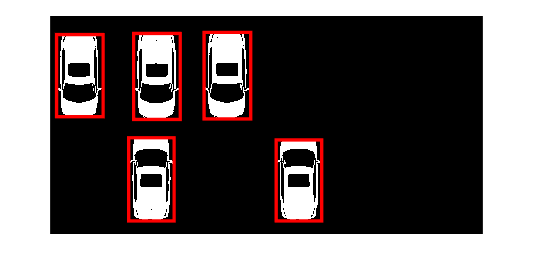

clc;clear;close all;

% Read in image and convert to grayscale
image = imread('MaskedImage2.png');
%grayImage = rgb2gray(image);

% Apply a threshold to create a binary image
binaryImage = image > 128;

% Perform blob analysis
blobAnalysis = vision.BlobAnalysis('MinimumBlobArea', 100);
[area, centroids, bboxes] = step(blobAnalysis, binaryImage);

% Display the image and draw bounding boxes around the detected blobs
imshow(image);
hold on;
for i = 1:size(bboxes, 1)
    rectangle('Position', bboxes(i, :), 'EdgeColor', 'r', 'LineWidth', 2);
end
hold off;

numberOfRectangles = size(bboxes, 1);
disp(numberOfRectangles)

     5



emptySlots= 12 - numberOfRectangles;
disp("Empty slots")

Empty slots


disp(emptySlots)

     7

